# WELCOME TO V768 - Measuring Vision with Psychophysics

## Lab 1 - Classical Methods

This lab covers the three classical psychophysics methods: (A) the method of limits, (B) the method of adjustment, and (C) the method of constant stimuli. For this lab, you will collect data using PsychoPy and analyze the data you generate.

### Learning Outcomes

(i.e., what you will be able to do at the end of this lab)

- Describe each of the three classical psychophysical methods.

- Identify the strengths and weaknesses of each method.

### Questions

#### A. Method of Limits

- How does the method of limits work? You can use this experiment as an exmple to explain. 

- Write a figure caption for the three panels in Figure 1.

- What are the potential weaknesses of the method of limits? (These can include practical problems with data collection.)

#### B. Method of Adjustment

- How does the method of adjustment work?

- Write a figure caption for the three panels in Figure 2. 

- What are the potential weaknesses of the method of adjustment?

#### C. Method of Constant Stimuli

- How does the method of constant stimuli work? 

- Write a figure caption for the two panels in Figure 3 and for Figure 4. 

- What are the potential weaknesses of the method of constant stimuli?

#### D. Wrap-Up

- Are these three experiments measuring the same thing? Explain the similarities and differences. Can you change the experiments so that they do measure the same thing?

## Part A. Method of Limits

### Step 1. Data collection

To collect data, open the PsychoPy ".psyexp" file in the folder titled "method-of-limits", and run that experiment. The instructions will appear on the screen before the trials begin. The experiment includes 10 trials.

### Step 2. Load your data

PsychoPy will save your experiment data to a "data" folder (inside of the same folder as the ".psyexp" file). The filename will start with the subject ID you used and end with the date/time of data collection.

Find the name of the ".csv" file containing your experiment data, and enter it below. Then run this section of code.

% change the filename to the one you generated during data collection
filename = 'method-of-limits/data/demo_method-of-limits_2025-01-06_16h24.27.517.csv';

% load the data table
limit_data = readtable(filename);

*Note: You can ignore the warning mentioning 'VariableNamingRule' that will appear above when you load your data. The warning results from PsychoPy's default variable naming choices and simply notifies you that MATLAB has edited the variable names to match its conventions. (Specifically, MATLAB replaces periods ['.'] with underscores ['_'] by default.)*

% remove the rows/columns associated with the instructions in psychopy
limit_data(1,:)=[];
remove = {'notes','instructions_started','instructions_stopped'};
limit_data(:,remove) = [];

### Step 3. Analyze your data

For this experiment, the stimulus was a sinusoidal grating with a Gaussian mask. The grayscale luminance range in PsychoPy is -1 to 1, where -1 is black, 1 is white, and 0 is middle gray. The background luminance was set to 0. Thus, if the stimulus contrast were 0, the grating would be middle gray (the same luminance as the background), and if the stimulus contrast were 1, the grating's luminance would range from black to white.

PsychoPy saved the stimulus contrast at the time of response. For trials that started with a low stimulus contrast, this is the contrast when the participant reported that the stimulus appeared. For trials that started with a high stimulus contrast, this is the contrast when the participant reported that the stimulus disappeared.

trials = 1:size(limit_data,1);

% extract the stimulus's initial contrast level, either high (1) or low (-1)
stimulus_start = limit_data.direction;

% extract the response data
contrast_response = limit_data.response;

#### Visualize the response per trial

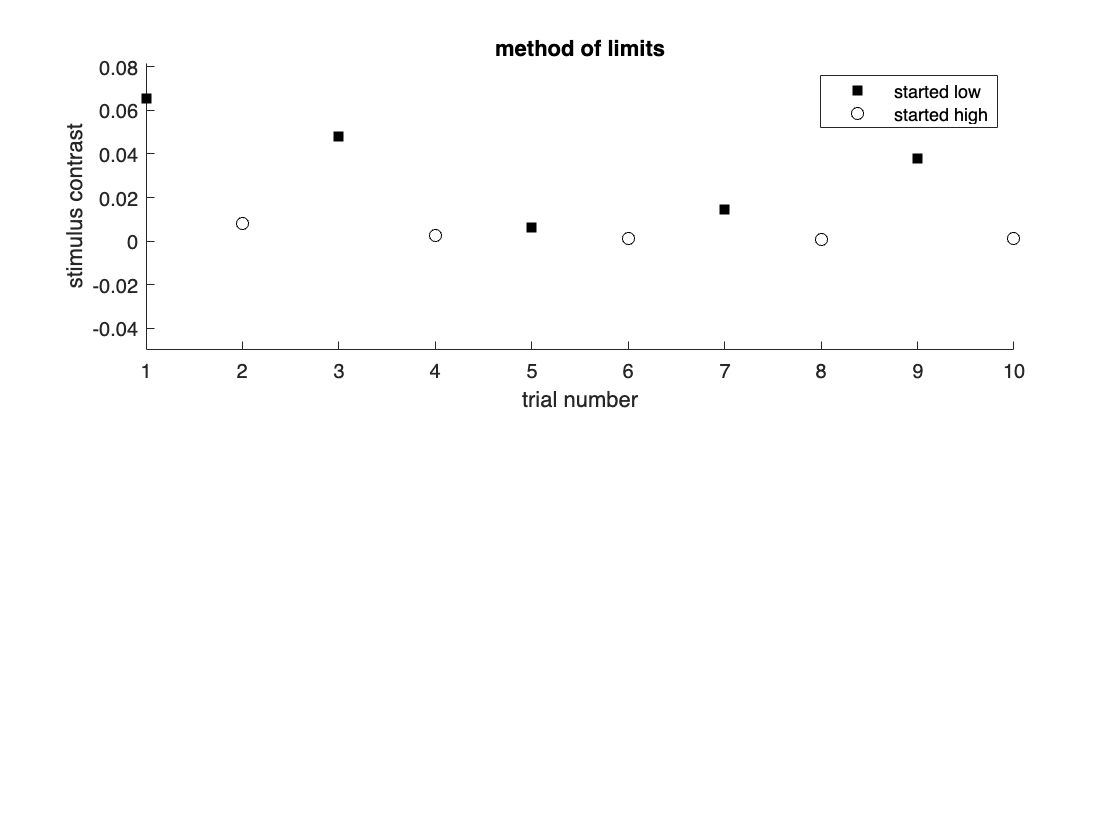

figure(1); clf; 
subplot(211); hold on;

% plot the trials that started at low contrast
ind = stimulus_start==-1;
plot(trials(ind),contrast_response(ind),'ks','MarkerFaceColor','k')

% plot the trials that started at high contrast
ind = stimulus_start==1;
plot(trials(ind),contrast_response(ind),'ko')

legend('started low','started high');
xlabel('trial number')
ylabel('stimulus contrast')
ylim([-.05,1.25*max(contrast_response)])

title('method of limits')

#### Plot the average reported contrast, separated by direction of change

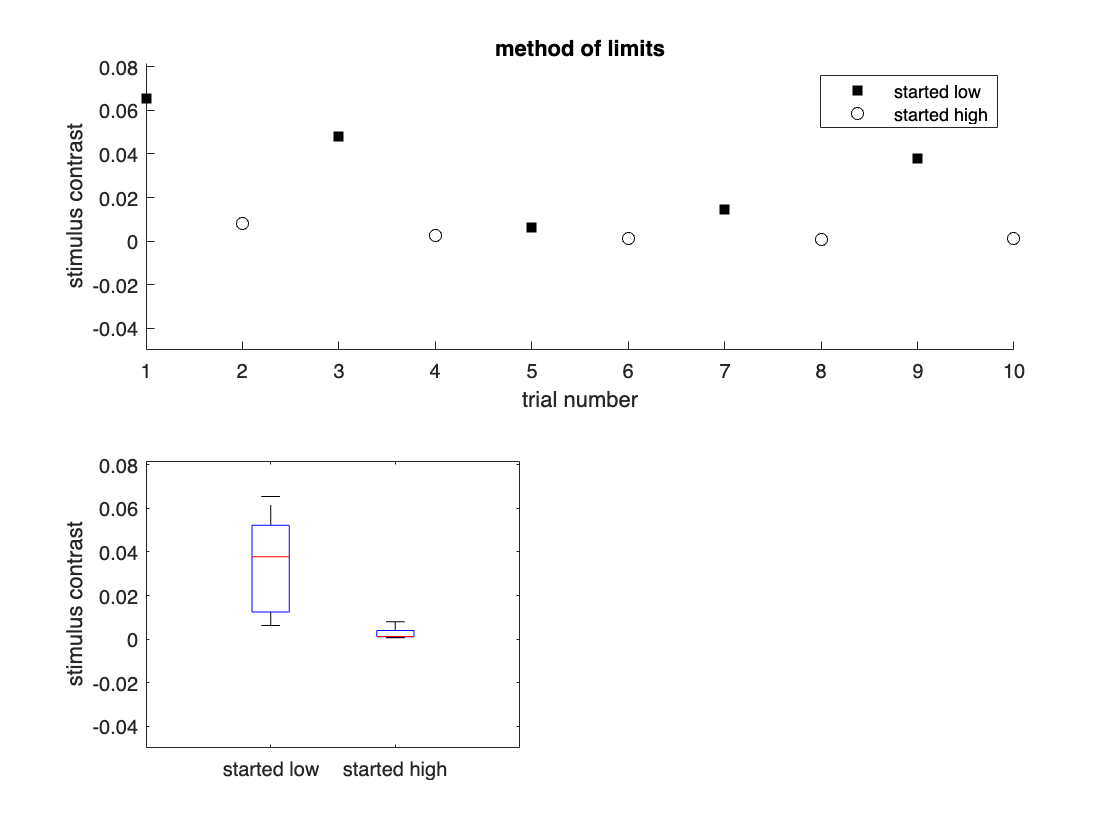

subplot(223); hold on;
boxplot(contrast_response,stimulus_start)
xlim([0,3])
ylim([-.05,1.25*max(contrast_response)])
ylabel('stimulus contrast')
set(gca,'XTickLabel',{'started low','started high'})

#### Plot the overall average reported contrast

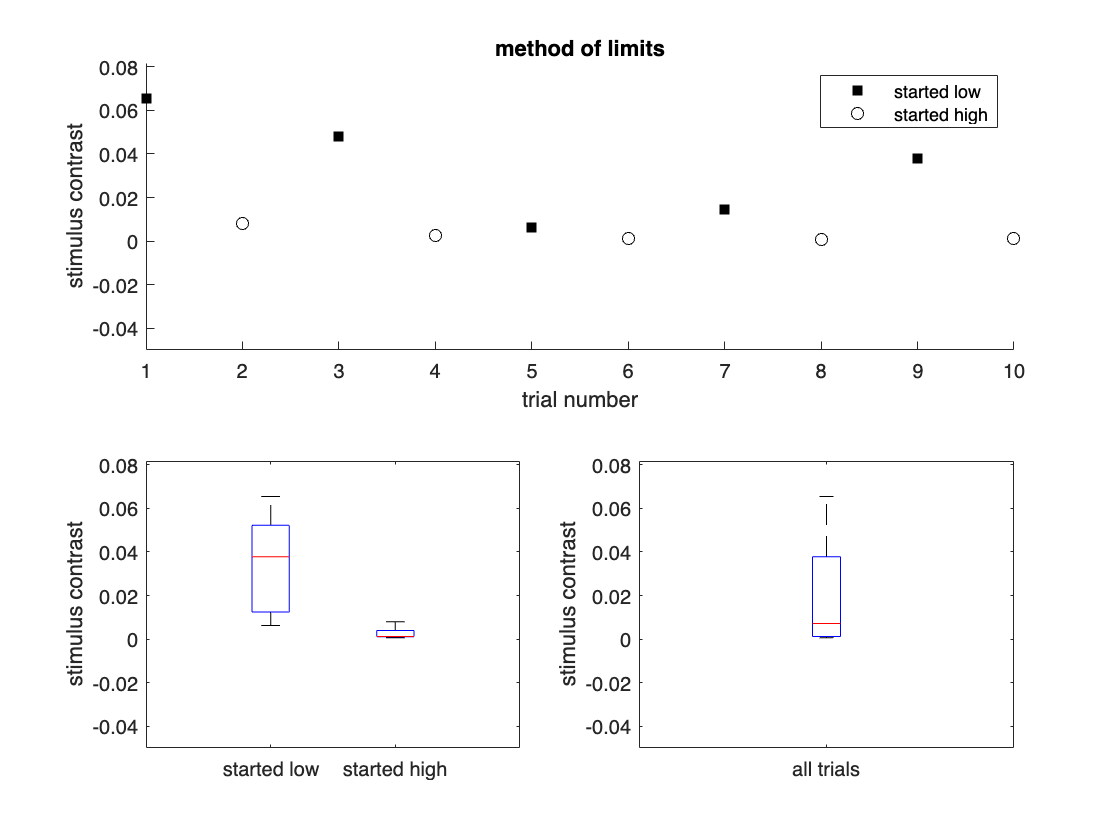

subplot(224); hold on;
boxplot(contrast_response)
xlim([0,2])
ylim([-.05,1.25*max(contrast_response)])
ylabel('stimulus contrast')
set(gca,'XTickLabel',{'all trials'})

## Part B. Method of Adjustment

### Step 1. Data collection

To collect data, open the PsychoPy ".psyexp" file in the folder titled "method-of-adjustment", and run that experiment. The instructions will appear on the screen before the trials begin. The experiment includes 20 trials.

### Step 2. Load your data

Before running this section of code, find the name of the ".csv" file containing your experiment data, and enter it below.

% change the filename to the one you generated during data collection
filename = 'method-of-adjustment/data/demo_method-of-adjustment_2025-01-06_16h30.16.790.csv';

% load the data table
adjust_data = readtable(filename);

*(Reminder: Ignore the 'VariableNamingRule' warning.)*

% remove the rows/columns associated with the instructions in psychopy
adjust_data(1,:)=[];
remove = {'notes','instructions_started','instructions_stopped'};
adjust_data(:,remove) = [];

### Step 3. Analyze your data

For this experiment, the target stimulus was a grating with a contrast of *e* to the power of -1 (approx. 0.37). The participant controlled the contrast of a second grating and pressed a button when the contrast of the two gratings seemed to match. PsychoPy saved the contrast of the controlled grating at the time of response, as well as the initial contrast level of that grating (either high or low).

trials = 1:size(adjust_data,1);

% extract the stimulus's initial contrast level, either high (1) or low (-1)
control_start = adjust_data.control;

% extract the target contrast per trial
% (only one was used in this experiment)
contrast_target = adjust_data.contrast_target;

% extract the response data
contrast_response = adjust_data.contrast_response;

#### Visualize the response per trial

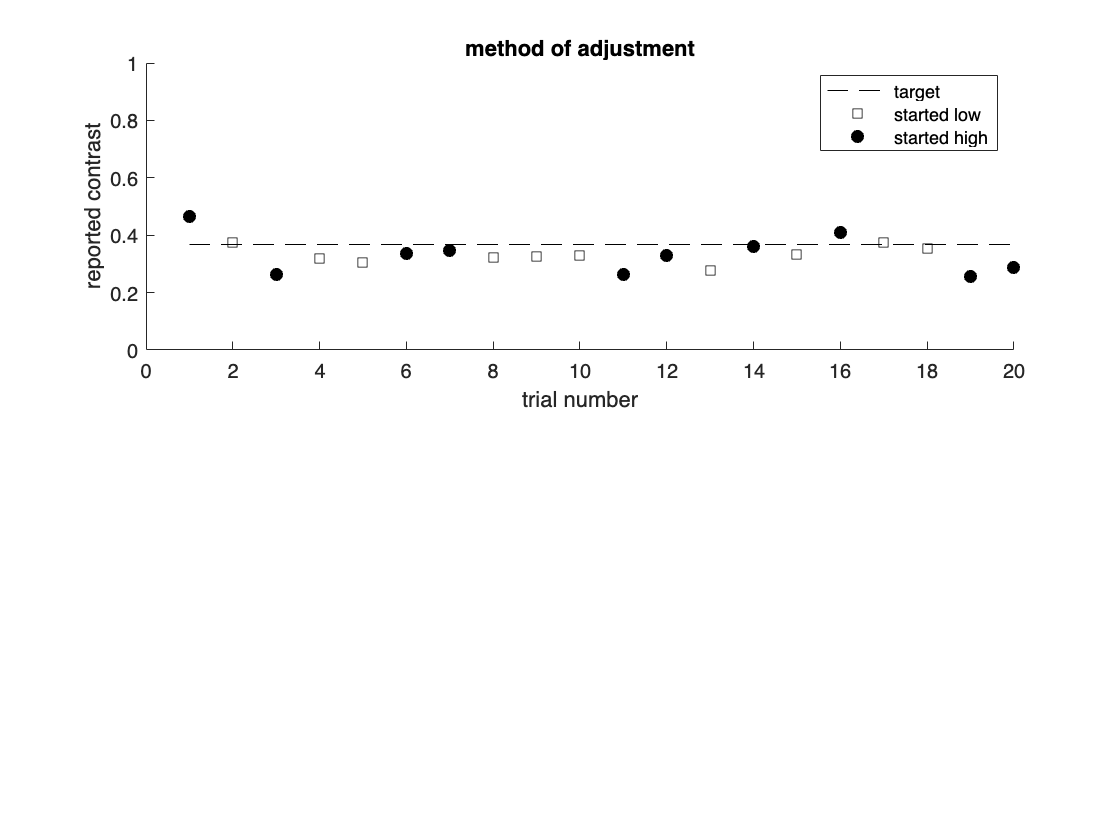

figure(2); clf; 
subplot(211); hold on;

% plot the contrast of the target grating
plot(trials,contrast_target,'k--')

% plot the trials that started at low contrast
ind = control_start==-1;
plot(trials(ind),contrast_response(ind),'ks')

% plot the trials that started at high contrast
ind = control_start==1;
plot(trials(ind),contrast_response(ind),'ko','MarkerFaceColor','k')

legend('target','started low','started high')
xlabel('trial number')
ylabel('reported contrast')
ylim([0,1])

title('method of adjustment')

#### Plot the average reported contrast, separated by starting point

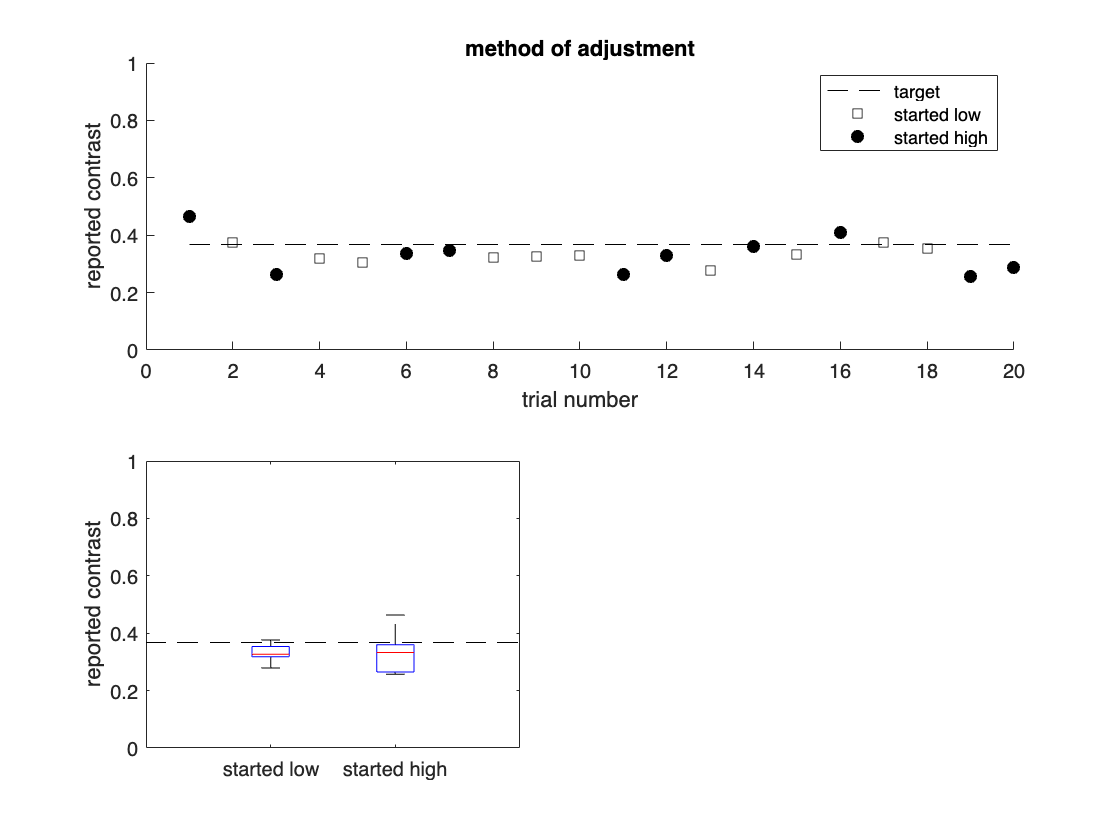

subplot(223); hold on;
boxplot(contrast_response,control_start)
set(gca,'XTickLabel',{'started low','started high'})
ylabel('reported contrast')

% mark the target contrast
plot([0,3],mean(contrast_target)*[1,1],'k--')
xlim([0,3])

#### Plot the overall average reported contrast

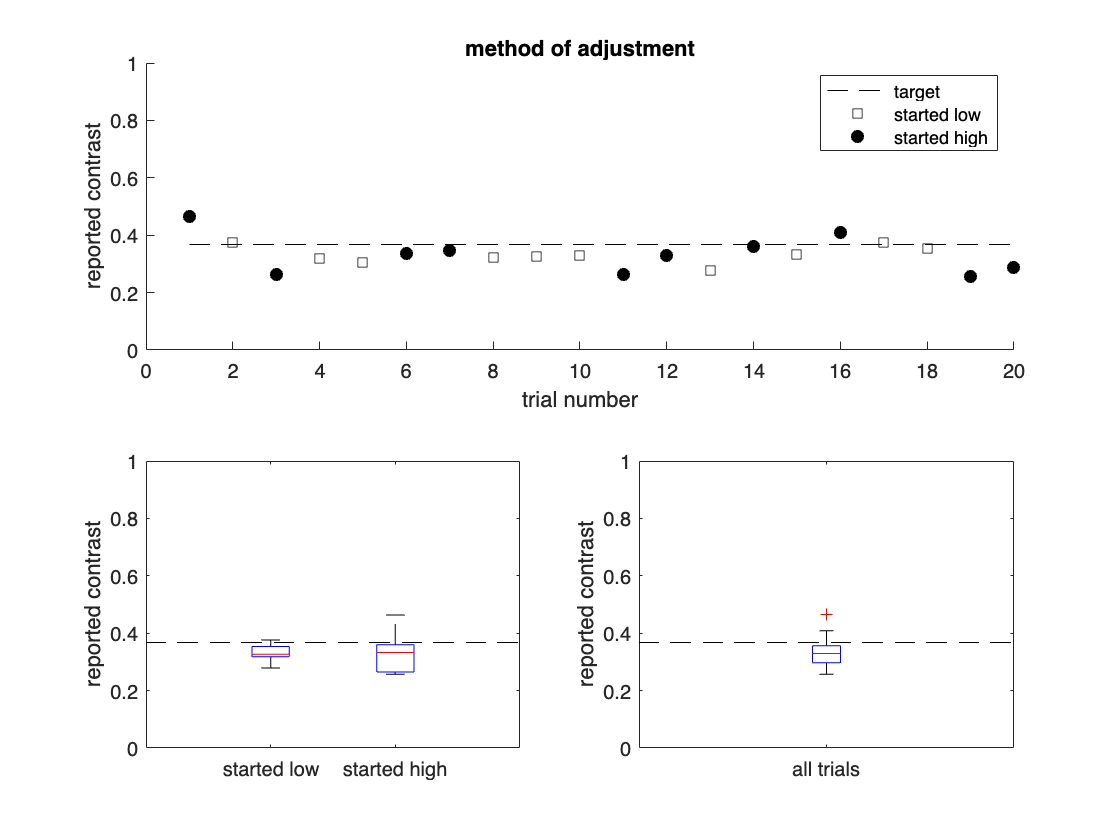

subplot(224); hold on;
boxplot(contrast_response)
set(gca,'XTickLabel',{'all trials'})
ylabel('reported contrast')

% mark the target contrast
plot([0,2],mean(contrast_target)*[1,1],'k--')
xlim([0,2])

## C. Method of Constant Stimuli

### Step 1. Data collection

To collect data, open the PsychoPy ".psyexp" file in the folder titled "method-of-constant-stimuli", and run that experiment. The instructions will appear on the screen before the trials begin. The experiment includes 210 trials.

### Step 2. Load your data

Before running this section of code, find the name of the ".csv" file containing your experiment data, and enter it below.

% change the filename to the one you generated during data collection
filename = 'method-of-constant-stimuli/data/demo_method_of_constant_stimuli_2025-01-16_21h16.39.043.csv';

% load the data table
constant_data = readtable(filename);

*(Reminder: Ignore the 'VariableNamingRule' warning.)*

% remove the rows/columns associated with the instructions in psychopy
constant_data(1,:)=[];
remove = {'notes','begin_experiment_started','begin_experiment_stopped'};
constant_data(:,remove) = [];

### Step 3. Analyze your data

For this experiment, PsychoPy saved the stimulus contrast and the participant's response per trial. The responses were stored as 'up' (stimulus present) or 'down' (stimulus not present).

trials = 1:size(constant_data,1);

% extract the stimulus's contrast level
stimulus_contrast = constant_data.contrast;

% extract the response data
response_key = constant_data.response_keys;

% convert the response key to true for up and false for down
response = strcmp(response_key,'up');

#### Visualize the response per trial

Plot each trial's stimulus contrast, along with an indicator of when the participant indicated the stimulus was not present (i.e., pressed down).

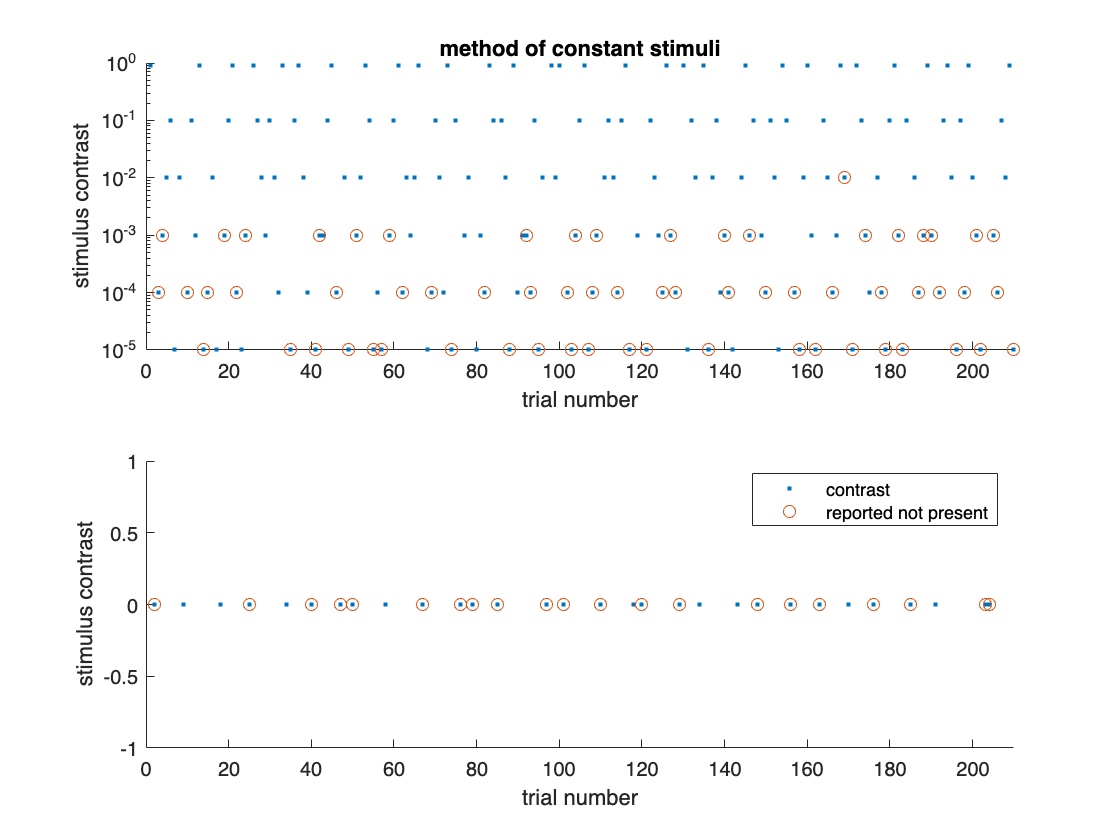

figure(3); clf;

% first, plot the stimulus contrast on a log scale
% (trials with zero contrast will not be included)
subplot(211); hold on;
plot(stimulus_contrast,'.');
set(gca,'YScale','log')
xlim([0,length(trials)])
xlabel('trial number')
ylabel('stimulus contrast')
title('method of constant stimuli')

% add a circle if the participant pressed down
chose_down = response==false;
plot(trials(chose_down),stimulus_contrast(chose_down),'o')

% second, plot the zero contrast trials (1/8th of the trials)
subplot(212); hold on;
was_zero = stimulus_contrast==0;
plot(trials(was_zero),stimulus_contrast(was_zero),'.');
xlim([0,length(trials)])
xlabel('trial number')
ylabel('stimulus contrast')

% add a circle if the participant pressed down
ind = was_zero & chose_down;
plot(trials(ind),stimulus_contrast(ind),'o');
legend('contrast','reported not present')

#### Plot percentage of stimuli reported present (up), as a function of contrast

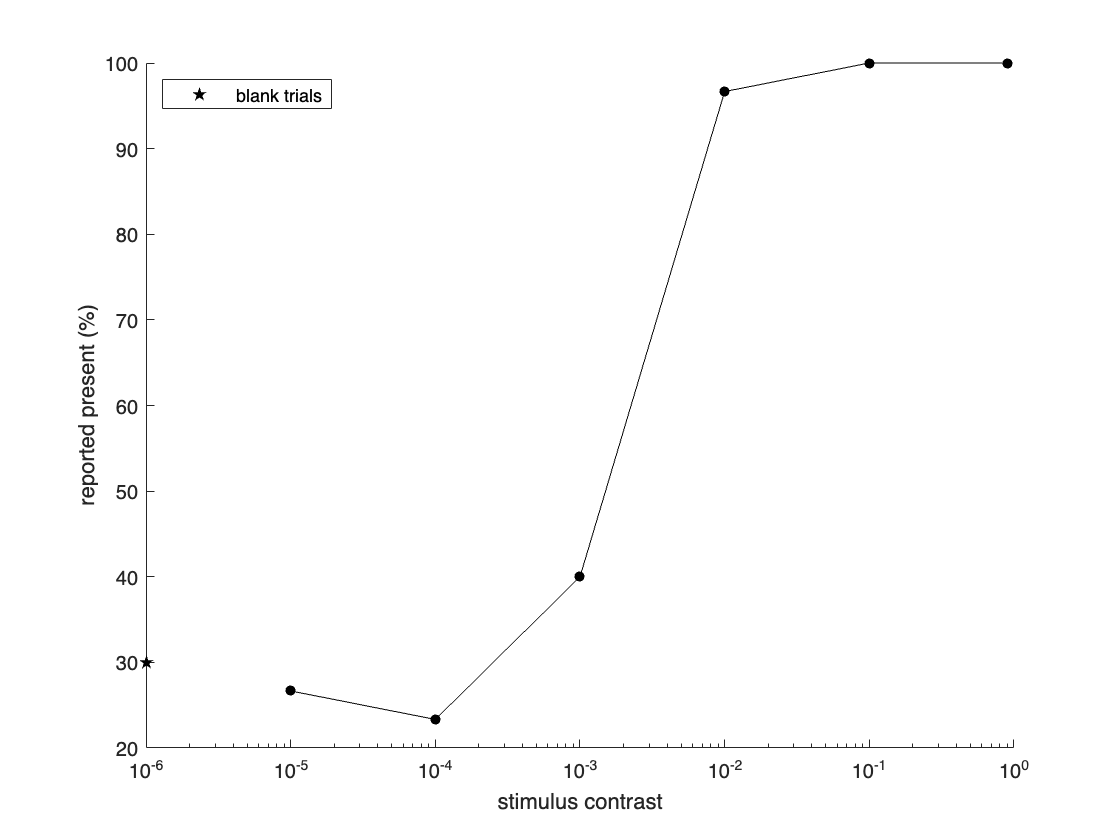

figure(4); clf; hold on;

% average across responses per contrast level
analysis_table = table(response, stimulus_contrast);
g = grpstats(analysis_table,'stimulus_contrast');

% plot with stimulus contrast on a log scale
% (trials with zero contrast will not be included)
plot(g.stimulus_contrast,g.mean_response*100,'k.-','MarkerSize',15)
set(gca,'XScale','log')
xlabel('stimulus contrast')
ylabel('reported present (%)')

% add a point for zero contrast (blank) trials
plot(g.stimulus_contrast(2)/10, g.mean_response(1)*100, ...
    'kpentagram', 'MarkerFaceColor','k')
legend({'','blank trials'}, 'Location','northwest')